# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/16*pi)*s + 0.3)/((1/64*pi)*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

% frequency response of uncertainty weights
figure
bodemag(wi)

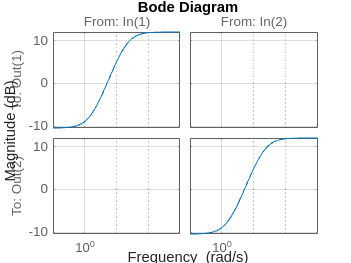

grid on

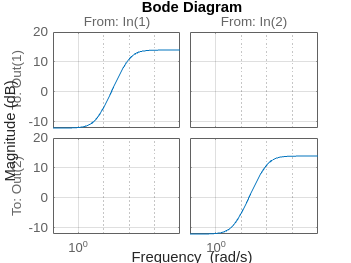


figure
bodemag(wo)
grid on


% uncertain TF singular values 

pb1 = ultidyn("idelta", 2)

Uncertain LTI dynamics "idelta" with 2 outputs, 2 inputs, and gain less than 1.
Block Properties


pb2 = ultidyn("odelta", 2)

Uncertain LTI dynamics "odelta" with 2 outputs, 2 inputs, and gain less than 1.
Block Properties


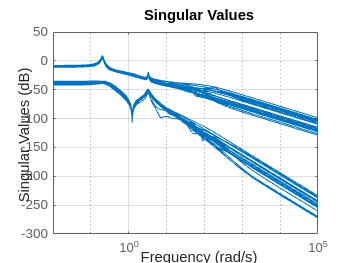


wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wid)*G*(eye(2)+wod);

figure
sigma(X)
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wu, wp, wo, wi, sumblock1, sumblock2, sumblock3, {'w', 'u', 'du', 'du'}, {'z1', 'z2', 'v', 'do', 'di'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms

% NS - generalised Nyquist
ol = MS_C*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

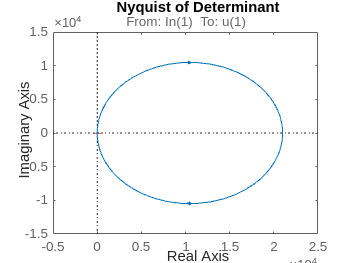


nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS 
% Build M
M11 = wi*MS_C*G/(eye(2)- MS_C*G);
M12 = wi*MS_C/(eye(2)- MS_C*G);
M21 = wo*G/(eye(2)- MS_C*G);
M22 = wo*MS_C*G/(eye(2)- MS_C*G);

M = [M11 M12;
    M21 M22];

% frequencies to check and shape of Delta block
omega=logspace(-3,3,61);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 61/61



% norm of bound
muNP=mubnds(:,1);
[muNPinf, muNPw]=norm(muNP,inf);